clear
addpath("frffit"); addpath('Assignment 2')


a) transfer function

m = 1; %[kg]
wc = 10 %[Hz} crossover frequency

wc =     10



H = tf(1,[m 0 0])

H =
 
   1
  ---
  s^2
 
Continuous-time transfer function.
Model Properties




P = abs(m*wc^2/(1 + i))

P =    7.0711e+01


D = P/wc

D =    7.0711e+00


C = tf([D P],1)

C =
 
  7.071 s + 70.71
 
Continuous-time transfer function.
Model Properties


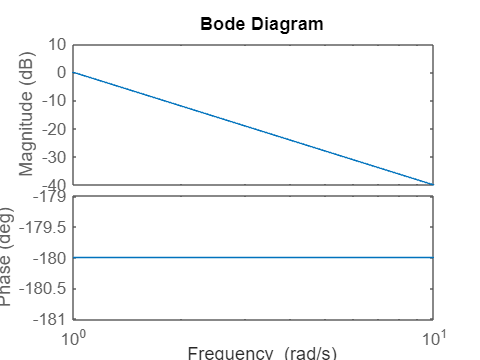

bode(H)

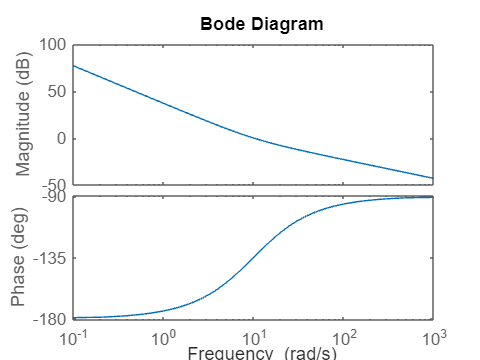

bode(H*C)

c) running simulation

stepsize = 0.001; %[s]
t_end = 120; %[s]
out = sim("two")

out =   Simulink.SimulationOutput:

                      d: [1x1 timeseries] 
                   tout: [120001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


u = out.u

  timeseries

  Common Properties:
            Name: ''
            Time: [120001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [120001x1 double]
        DataInfo: 

d = out.d

  timeseries

  Common Properties:
            Name: ''
            Time: [120001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [120001x1 double]
        DataInfo: 

fs = 1/stepsize

fs =         1000


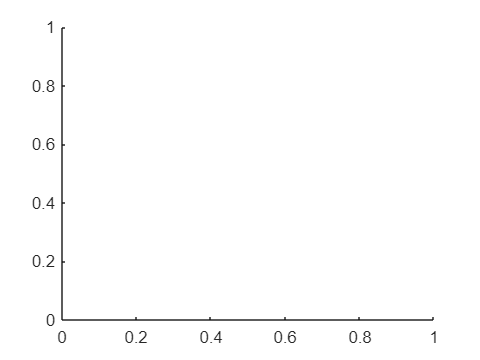

windowsize = 1; %[s]
window = windowsize/stepsize;
figure()
hold on

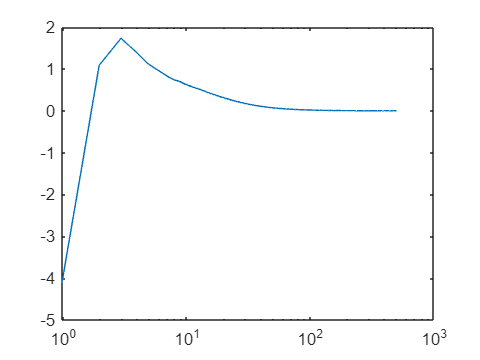

%plot(r.Time,r.Data)
%plot(y.Time,y.Data)

%Tf estimate
figure()
[P, F] = tfestimate(d.Data,u.Data,window,[],[],fs);

semilogx(F,mag2db(abs(P)))

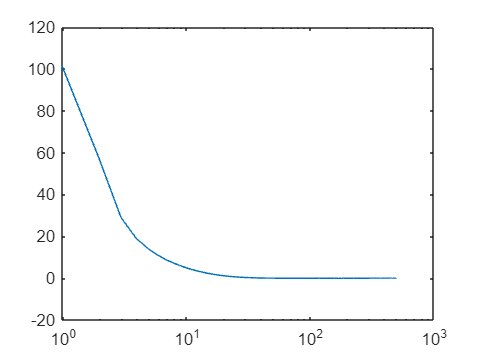

Unable to resolve the name 'r.Data'.

semilogx(F,angle(P)/pi*180)

d) Coherence

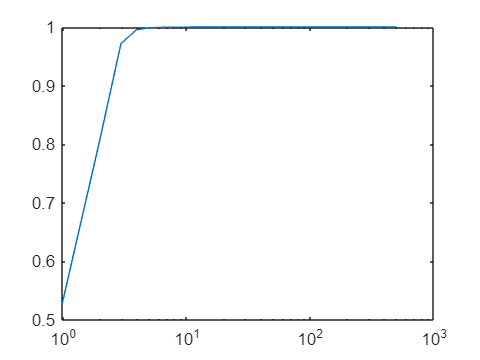

[coherence_ry, F] = mscohere(d.Data,u.Data,window,[],[],fs);
semilogx(F,coherence_ry)

e)

L = 1./P-1

L =   -8.2153e+00 + 0.0000e+00i
  -1.3179e+00 - 1.5721e+00i
  -5.1954e-01 - 7.4024e-01i
  -2.8353e-01 - 3.9755e-01i
  -1.9442e-01 - 2.7558e-01i
  -1.4670e-01 - 2.1304e-01i
  -1.2128e-01 - 1.6869e-01i
  -1.0236e-01 - 1.3778e-01i
  -8.8945e-02 - 1.1499e-01i
  -8.2284e-02 - 9.7130e-02i


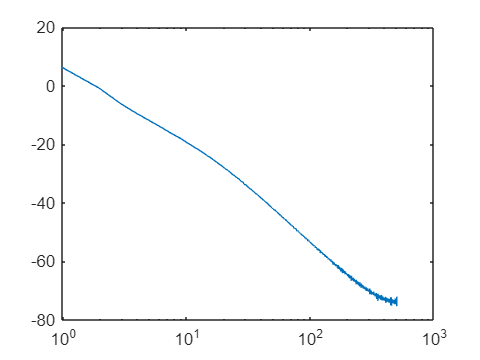

semilogx(F,mag2db(abs(L)))

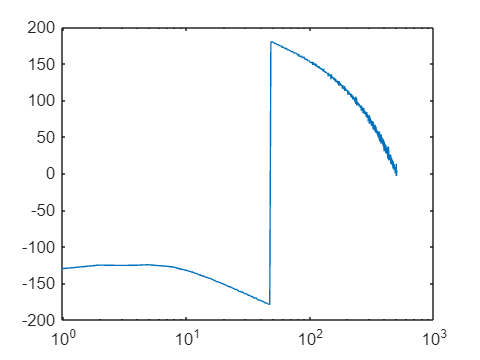

semilogx(F,angle(L)/pi*180)